close all; clear; clc;

# Step Test- discrete

**filename**: steps_dis.mlx

**keywords:** Discrete Sweep Test Visual, testmatrix

**file created by:** {20180710, NAME}

**last updated on:** {20180710}

**primary purpose:** {Enter the primary purpose and primary input and output variables.}

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00229190597677565;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('stepdis.mat');
time = stepdis(:,1);          % [sec]
ESC_us = stepdis(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = stepdis(:,3);             % [ft.lbf]
T = stepdis(:,4);             % [lbf]
Input_V = stepdis(:,5);       % [Volts]
Input_A = stepdis(:,6);       % [Amps]
rot_speed = stepdis(:,7);     % [rad/sec]
P_in_W = stepdis(:,8);        % [Watts]
P_out_W = stepdis(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = stepdis(:,10);    % [%]
Prop_Eff = stepdis(:,11);     % [lbf/Watts]
Overall_Eff = stepdis(:,12);  % [lbf/Watts]  
Motor_Temp = stepdis(:,13);   % [F]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed .* radius).^(2) .* radius);

## Plots

{This is the section for generating output tables, plots, etc.}

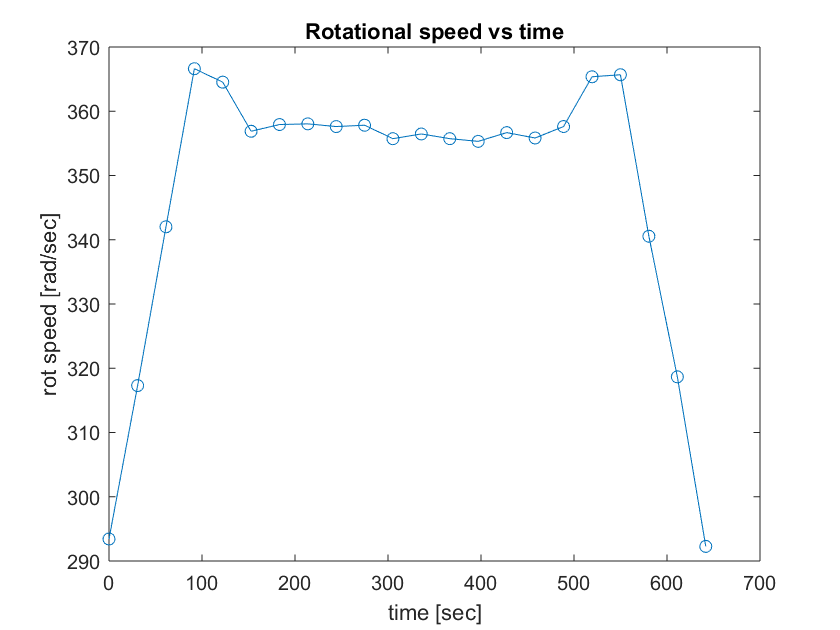

figure(1)
plot(time, rot_speed, 'o-'); title('Rotational speed vs time');
xlabel('time [sec]'); ylabel('rot speed [rad/sec]');

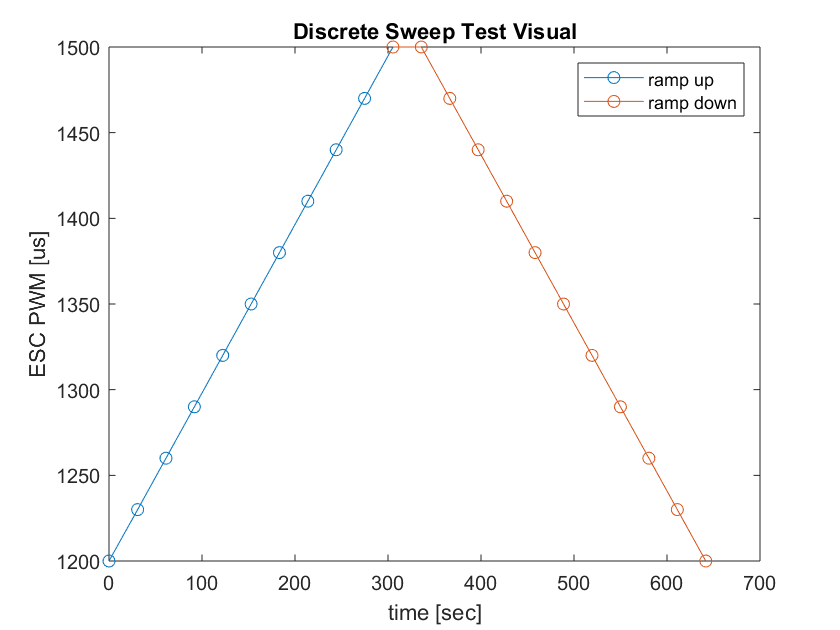


x = (1:11);
y = (11:22);

figure(2)
plot(time(x), ESC_us(x), 'o-',time(y), ESC_us(y), 'o-'); title('Discrete Sweep Test Visual');
xlabel('time [sec]'); ylabel('ESC PWM [us]'); legend('ramp up','ramp down');

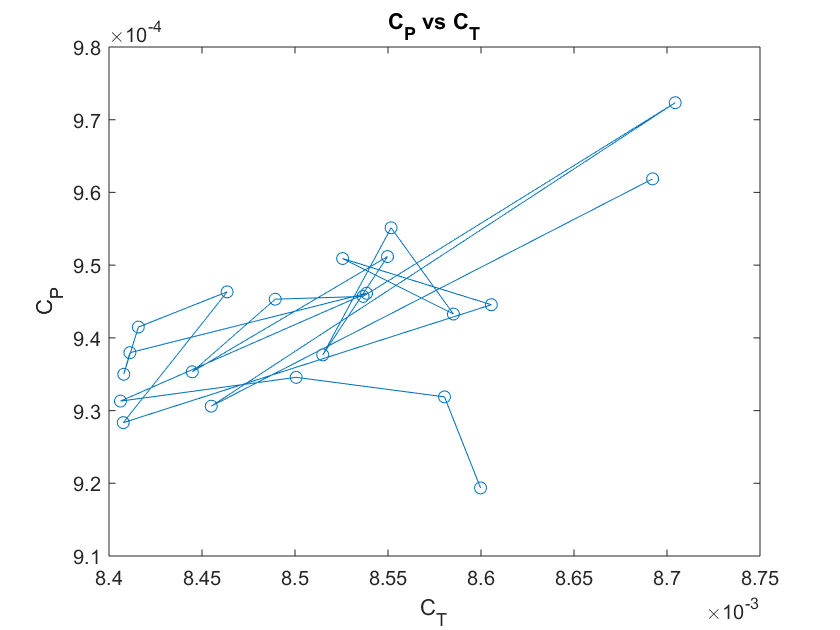


figure(2)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')